# Symbolic Math

## Problem 1

Evaluate the following limits if they exist:

syms x

a. $\lim_{x\to0} \frac{sin x}{x}$

limit(sin(x)/x, x, 0)

$$ans = 1$$

b. $\lim_{x\to\infty} \frac{x^3+3x^2-5}{2x^3-6x}$

limit((x^3 + 3*x^2 - 5) / (2*x^3 - 6*x), x, sym(inf))

$$ans = \frac{1}{2}$$

c. $\lim_{x\to0^+} \frac{1}{x}$

limit(1/x, x, 0, 'right')

$$ans = \infty$$

## Problem 2

Find the derivatives of the following functions:

syms x

a. $y = 3x^3 + 7x^2 - 5$

diff(3*x^3 + 7*x^2 - 5)

$$ans = 9\,x^{2}+14\,x$$

b. $y  = \sqrt{1+x^4}$

diff(sqrt(1 + x^4))

$$ans = \frac{2\,x^{3}}{\sqrt{x^{4}+1}}$$

c. $y=x^{\ln x}$

diff(x^log(x))

$$ans = x^{\log\left(x\right)-1}\,\log\left(x\right)+\frac{x^{\log\left(x\right)}\,\log\left(x\right)}{x}$$

## Problem 3

Evaluate the following definite integrals

syms x

a. $\int_{x=0}^{1} \left(3x^3 + 2x^2 - 5 \right) \, dx$

int(3*x^3 + 2*x^2 - 5, 0, 1)

$$ans = -\frac{43}{12}$$

b. $\int_{x=0}^{1} \left( \frac{1}{\sqrt{x}} \right) \,dx$

int(1/sqrt(x), 0, 1)

$$ans = 2$$

c. $\int_{x=0}^{1} \left ( e^{-x^2} \right ) \,dx$

int(exp(-x^2), 0, 1)

$$ans = \frac{\sqrt{\pi }\,\mathrm{erf}\left(1\right)}{2}$$

## Problem 4

Graph the following:

syms x y t

a. $y = e^{-x^2} ~ x \in \left [-5, 5 \right ]$

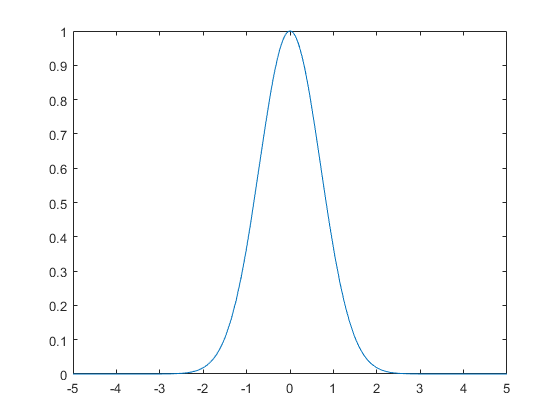

fplot(exp(-x^2), [-5,5])

b. $x^2 - 2xy - y^2 = 7$

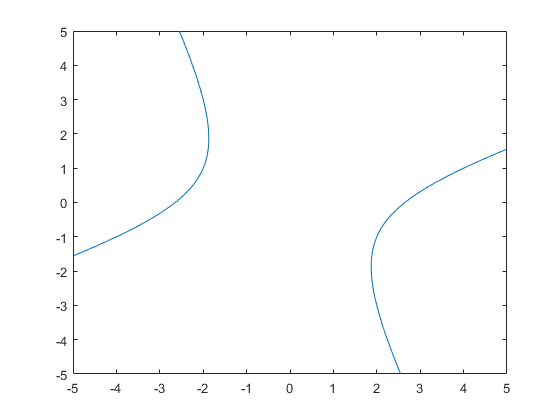

fimplicit(x^2 - 2*x*y - y^2 == 7)

c. $\[\begin{cases} x=t^2 - 3t\\ y=t^3 - 9t \end{cases} ~ t\in [-4,4]\]$

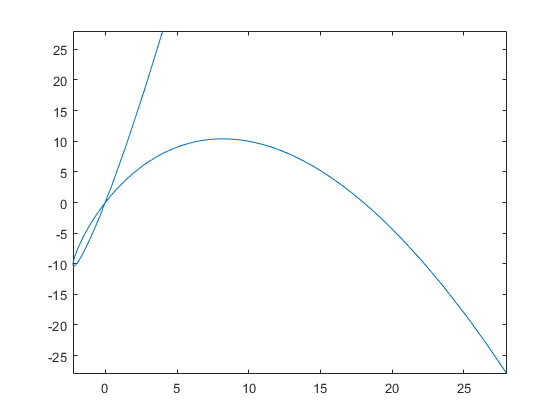

x(t) = t^2 - 3*t;
y(t) = t^3 - 9*t;
fplot(x(t), y(t), [-4, 4])

## Problem 5

Show the differential equations:

a. $\frac{dy}{dx} = \frac{x}{2y} ~~~ y(1) = 1$

syms x y(x)
eqn = [diff(y, x) == x/(2*y), y(1) == 1];
y = dsolve(eqn)

$$y = \frac{\sqrt{2}\,\sqrt{x^{2}+1}}{2}$$

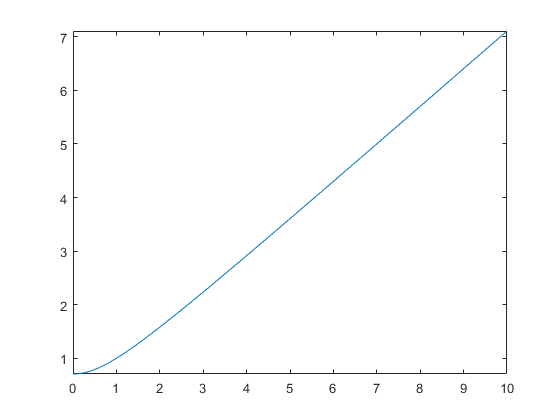

fplot(y, [0 10])

b. $\frac{dy}{dx} = \frac{-y}{x} ~~~ y(2) = 3$

syms x y(x)
eqn = [diff(y, x) == -y/x, y(2) == 3];
y = dsolve(eqn)

$$y = \frac{6}{x}$$

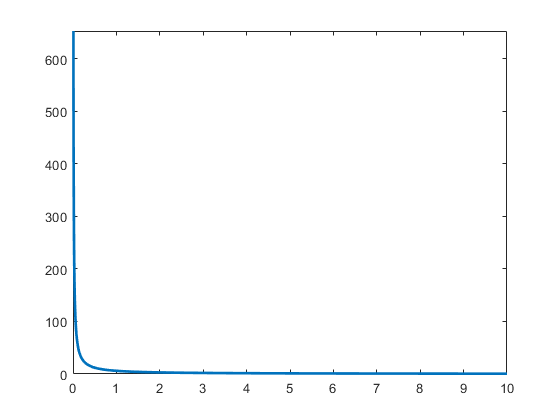

fplot(y, [0 10], 'LineWidth', 2)

c. $\frac{d^2x}{dt^2} + 5 \frac{dx}{dt} + 6x = 0 ~~~ x(0)=1 ~ \dot{x}(0) = 0$

syms x(t) t
eqn = [diff(x,t,2) + 5*diff(x,t,1) + 6*x == 0; x(0) == 1; subs(diff(x,t,1), t, 0) == 0];
x = dsolve(eqn)

$$x = {\mathrm{e}}^{-3\,t}\,\left(3\,{\mathrm{e}}^{t}-2\right)$$

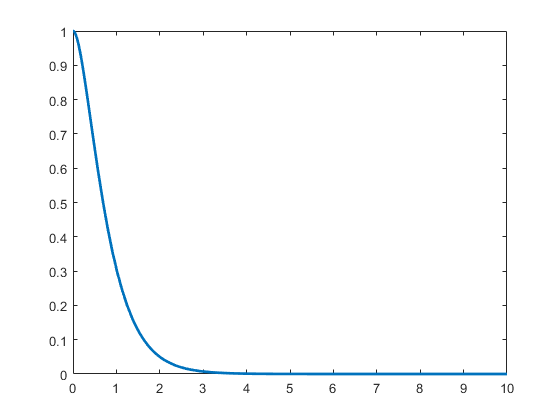

fplot(x, [0 10], 'LineWidth', 2)

## Problem 6

Compute the fifth derivative of $cos \left ( x^2 \right )$

syms x 
diff(cos(x^2), x, 5)

$$ans = 120\,x\,\sin\left(x^{2}\right)+160\,x^{3}\,\cos\left(x^{2}\right)-32\,x^{5}\,\sin\left(x^{2}\right)$$

## Problem 7

Compute an expanded form of the expression $\left ( x^2 - y \right )^5$

syms x y
expand((x^2 - y)^5)

$$ans = x^{10}-5\,x^{8}\,y+10\,x^{6}\,y^{2}-10\,x^{4}\,y^{3}+5\,x^{2}\,y^{4}-y^{5}$$

## Problem 8

Generate a plot of the function $\frac{sin x}{x} ~ x \in [-10, 10]$

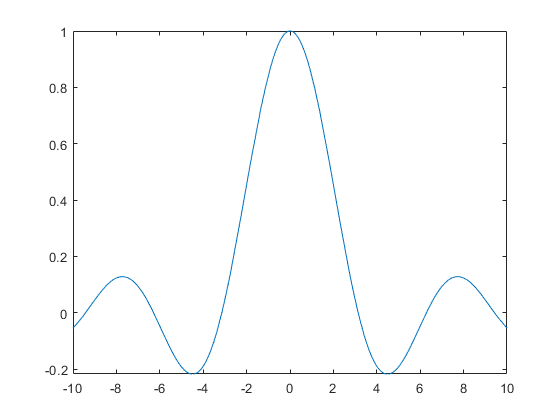

syms x
fplot(sin(x)/x, [-10 10])

## Problem 9

Find a simplified expression for the following sum $\sum_{k=1}^{n} \left ( k^2 + 2k + 1 \right )$

syms k n
simplify(symsum(k^2 + 2*k + 1, 1, n))

$$ans = \frac{n\,\left(2\,n^{2}+9\,n+13\right)}{6}$$

## Problem 10

Compute $\left(2A - 8B)$, $AB$, and $(A - B)^{-1}$ for the following matrices:


$$A = \pmatrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7 & 8 & 9} ~~  B = \pmatrix{1 & 1 & 0 \cr 1 & 0 & 1 \cr 0 & 1 & 0} $$


syms A B
A = sym([1 2 3; 4 5 6; 7 8 9]);
B = sym([1 1 0; 1 0 1; 0 1 0]);
2*A - 8*B

$$ans = \left(\begin{array}{ccc} -6 & -4 & 6\\ 0 & 10 & 4\\ 14 & 8 & 18 \end{array}\right)$$

A*B

$$ans = \left(\begin{array}{ccc} 3 & 4 & 2\\ 9 & 10 & 5\\ 15 & 16 & 8 \end{array}\right)$$

(A - B) ^ -1

$$ans = \left(\begin{array}{ccc} -\frac{5}{17} & -\frac{6}{17} & \frac{5}{17}\\ -\frac{4}{17} & \frac{21}{34} & -\frac{9}{34}\\ \frac{7}{17} & -\frac{7}{34} & \frac{3}{34} \end{array}\right)$$

## Problem 11

Find all solutions to the following system of linear equations


$$\begin{array} {lcl} 3x-2y+3z=10 \\ x-y=-4 \\ -x+y-z=20 \end{array}$$


syms x y z

% I'll use the matrix approach to solve this system: 
% Av=b
%  v=(A^-1)b
A = sym([3 -2 3; 1 -1 0; -1 1 -1]);
v = [x; y; z];
b = sym([10; -4; 20]);
isempty(null(A))

ans = logical
   1

Since the Null space of A is empty, the solutions to this system are uniqe

% Evaluate solution
[x; y; z] == (A^-1)*b

$$ans = \left(\begin{array}{c} x=66\\ y=70\\ z=-16 \end{array}\right)$$

## Problem 12

Compute the following interval:


$$\int_{-\pi}^{\pi} \left ( 3 + 2\sin  x + 3\cos x \right ) \left (1 + 2\sin x \right )\,dx$$


syms x
int((3 + 2*sin(x) + 3*cos(x))*(1 + 2*sin(x)), [-pi pi])

$$ans = 10\,\pi$$

## Problem 13

A certain metabolite A in a cell is converted to B and C at rates of $k_1 = 0.5 min^{-1}$ and $k_3 = 0.3min^{-1}$, respectively. The reverse reactions occur at rates of $k_2 = 0.2min^{-1}$ and $k_4 = 0.1min^{-1}$, respectively. Initially, the concentrations of A, B and C are $700\,nM$, $500\,nM$, and $0\,nM$ respectively.

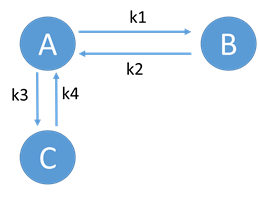

syms k_1 k_2 k_3 k_4 A(t) B(t) C(t) t
sys = [diff(A(t), t) == k_2*B(t) + k_4*C(t) - (k_1 + k_3)*A(t);
	     diff(B(t), t) == k_1*A(t) - k_2*B(t);
			 diff(C(t), t) == k_3*A(t) - k_4*C(t);
			 A(0) == 700; B(0) == 500; C(0) == 0];
ode = subs(sys, {k_1, k_2, k_3, k_4}, cellfun(@vpa, {0.5, 0.2, 0.3, 0.1}))

$$ode = \left(\begin{array}{c} \frac{\partial }{\partial t}A\left(t\right)=0.2\,B\left(t\right)-0.8\,A\left(t\right)+0.1\,C\left(t\right)\\ \frac{\partial }{\partial t}B\left(t\right)=0.5\,A\left(t\right)-0.2\,B\left(t\right)\\ \frac{\partial }{\partial t}C\left(t\right)=0.3\,A\left(t\right)-0.1\,C\left(t\right)\\ A\left(0\right)=700\\ B\left(0\right)=500\\ C\left(0\right)=0 \end{array}\right)$$

a. Solve the system of ODEs for the concentrations of these metabolites. Plot their concentrations over time.

soln = dsolve(ode);
A(t) = simplify(soln.A)

$$A(t) = 45.164974744738218654616688968086\,{\mathrm{e}}^{-0.13466880685409625737078686275462\,t}+470.21964063987716596076792641653\,{\mathrm{e}}^{-0.96533119314590374262921313724538\,t}+184.61538461538461538461538461538$$

B(t) = simplify(soln.B)

$$B(t) = 345.66164009795110206643841890523\,{\mathrm{e}}^{-0.13466880685409625737078686275462\,t}-307.20010163641264052797688044369\,{\mathrm{e}}^{-0.96533119314590374262921313724538\,t}+461.53846153846153846153846153846$$

C(t) = simplify(soln.C)

$$C(t) = 553.84615384615384615384615384615-163.01953900346452543279104597284\,{\mathrm{e}}^{-0.96533119314590374262921313724538\,t}-390.82661484268932072105510787331\,{\mathrm{e}}^{-0.13466880685409625737078686275462\,t}$$

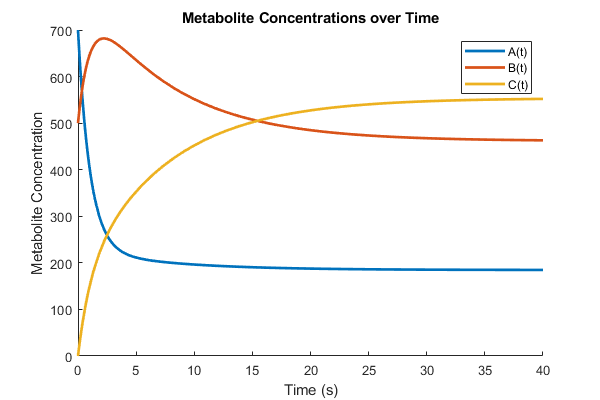

% Plot concentration
figure('Position', [0 0 600 400]);
hold on;
fplot(A(t), [0 40], 'LineWidth', 2);
fplot(B(t), [0 40], 'LineWidth', 2);
fplot(C(t), [0 40], 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Metabolite Concentration');
title('Metabolite Concentrations over Time');
hold off;
legend({'A(t)', 'B(t)', 'C(t)'})

b. At what time are the concentrations of A and B equal?

t_equal = solve(A(t) == B(t), t, 'Real', true)

$$t\_equal = 0.33193208047118125966764239874726$$

c. What are the steady-state concentrations of the metabolites?

% Steady state concentration of A
limit(A(t), t, inf)

$$ans = 184.61538461538461538461538461538$$

% Steady state concentration of B
limit(B(t), t, inf)

$$ans = 461.53846153846153846153846153846$$

% Steady state concentration of C
limit(C(t), t, inf)

$$ans = 553.84615384615384615384615384615$$

## Problem 14

The differential equation $\frac{1}{A^2} \frac{d^2x}{dt^2} + x = \sin \left(Bt\right)$ is the governing equation for a "forced harmonic oscillator." It describes the behavior of an enerfy conserving system that vibrates freely at a frequency $A\,\left(\frac{radians}{sec}\right)$, which is excited by an external force at frequency $B$. Use symbolic math to solve the equation with initial conditions $x=0$ and $\frac{dx}{dt}=0$ (*simplify the solution, and use *`IgnoreSpecialCases`). Plot the solution for a time interval of $60\,sec$, with $A=1$ and $B=1.2$.

syms A B x(t) t
ode = [(1/(A^2) * diff(x(t), t, 2)) + x == sin(B*t); x(0) == 0; subs(diff(x(t), t) == 0, t, 0)];
%ode = subs(ode, {A, B}, {1, 1.2});
% Solve ode
soln = simplify(dsolve(ode))

$$soln = -\frac{A\,{\mathrm{e}}^{-A\,t\,\mathrm{i}}\,\left(B-B\,{\mathrm{e}}^{2\,A\,t\,\mathrm{i}}+2\,A\,{\mathrm{e}}^{A\,t\,\mathrm{i}}\,\sin\left(B\,t\right)\,\mathrm{i}\right)\,\mathrm{i}}{2\,\left(A^{2}-B^{2}\right)}$$

ode = subs(ode, {A, B}, {1, 1.2});
% plot solution
figure;
fplot(soln, [0 60])
xlabel('t'); ylabel('x');

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

$$ans = \frac{25\,{\mathrm{e}}^{-t\,\mathrm{i}}\,\left(\frac{6}{5}-\frac{6\,{\mathrm{e}}^{2\,t\,\mathrm{i}}}{5}+2\,\sin\left(\frac{6\,t}{5}\right)\,{\mathrm{e}}^{t\,\mathrm{i}}\,\mathrm{i}\right)\,\mathrm{i}}{22}$$